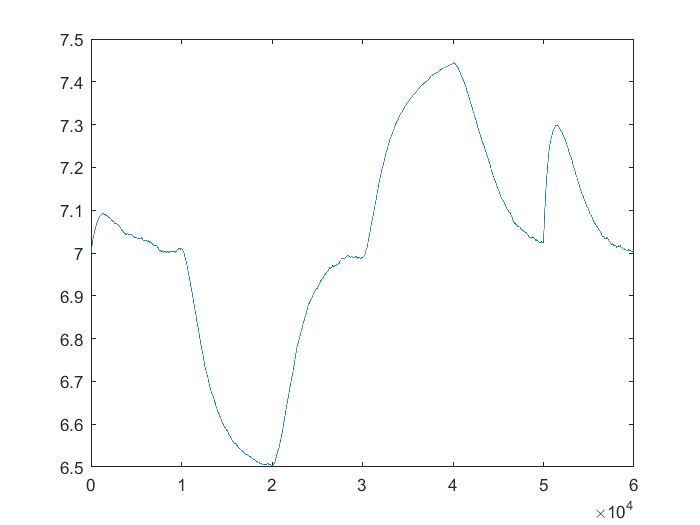

% clear 
% close all
% clc

kw = 10^-14;
Ca = 10^-6;
Cb = 10^-6;
V = 30;
Fa = 0.016667;
y_e = 7;
uep = 0.0167;

K = 0.01;
Ti =  900.09;
Tt =  0.01*Ti;

% Izbor kontrolera (linearni/fazi PI kontroler)
sel = 2;

du_max = 0.0691;
Ku_cap = 10*Fa/2;
Kp_cap = K / Ti / Ku_cap / 1;
Kd_cap = K/Ku_cap;

Ku_cap = du_max / 2 / 0.1;
Kp_cap = K / Ti / Ku_cap / 1;
Kd_cap = K/Ku_cap;

lin_fpd = readfis('lin_fpd_ostar');

figure
plot(out.t, out.y)

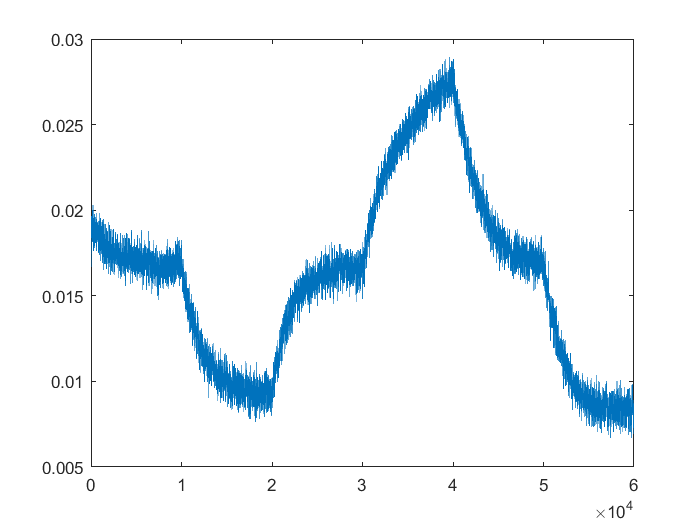

plot(out.t, out.u)

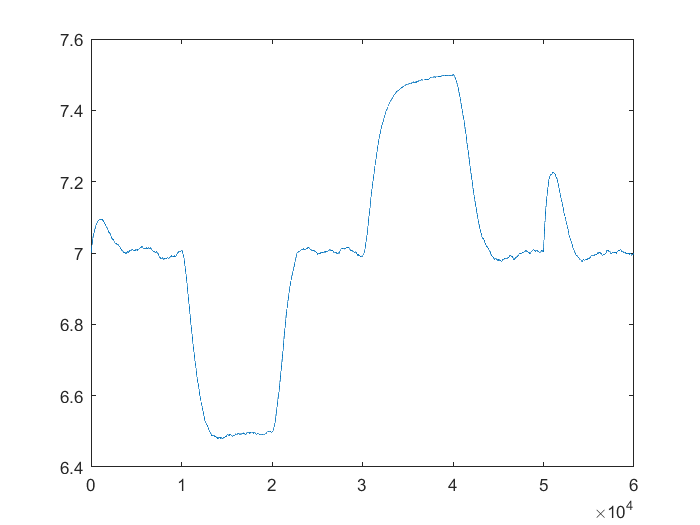


%naborana povrs
Ku_cap = du_max / 2 / 0.1;
Kp_cap = K / Ti / Ku_cap / 1 * 20;
Kd_cap = K/Ku_cap*20;

figure
plot(out.t, out.y)

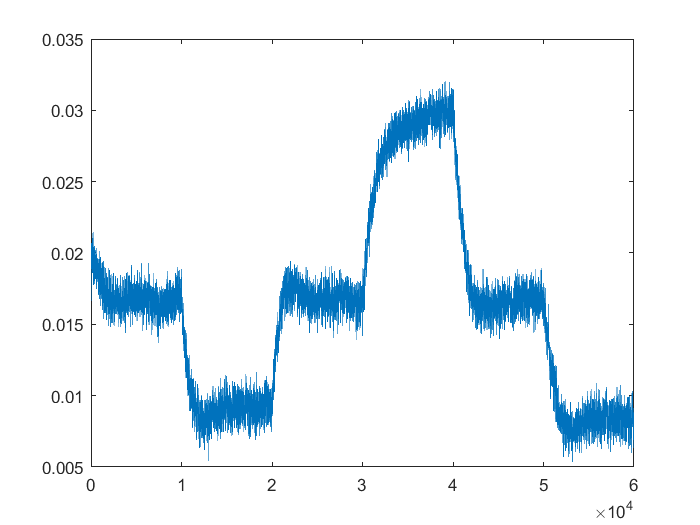

plot(out.t, out.u)


%blaga povrs

Ku_cap = du_max / 2 / 0.1;
Kp_cap = K / Ti / Ku_cap / 1 * 20;
Kd_cap = K/Ku_cap * 40;

figure
plot(out.t, out.y)
plot(out.t, out.u)